# Design Project

clear; close; clc;

## Initialization

% Declare Load Case Variables
P_y = -8000; % Bending load acting downwards (lb)
P_x = 65e3; % axial load acting in tension (lb)

% Given geometry
d_o = 8; % outer diameter (in)
L = 36; % length (in)

% Assumed parameters before sizing
t = 0.0052 * 16; % thickness (in)
x = 0; % distance in x (in)

%t=1;

% Computed geometry
r_o = d_o / 2; % outer radius (in)
r_i = r_o - t; % inner radius (in)
r_m = r_o - t / 2; % average radius (in)




% Q(gamma) = (r_o^2-r_i^2)/2.*(2*gamma - 2*sin(gamma)) .* 2/3*(r_o^3-r_i^3)./(r_o^2-r_i^2).*(sin(gamma)./gamma)
% 
% tau(y) = P_y.*Q(gamma)./(I*t)
% fplot(@(y) tau(gamma),[0,2*pi], "LineWidth",2)
gamma = linspace(0,pi/2)

gamma =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775


%gamma = linspace(-2*pi,2*pi)
%gamma = [0, pi/4, pi/2, pi, 3*pi/4, 2*pi]+.00001
%gamma = linspace(0,pi)
%gamma = linspace(pi,2*pi)
q = bendingShearFlow(r_o, t, P_y, gamma)

q =        NaN   -0.0009   -0.0069   -0.0231   -0.0548   -0.1069   -0.1847   -0.2930   -0.4370   -0.6217   -0.8519   -1.1326   -1.4686   -1.8646   -2.3254   -2.8557   -3.4598   -4.1424   -4.9079   -5.7605   -6.7044   -7.7437   -8.8825  -10.1246  -11.4738  -12.9337  -14.5079  -16.1997  -18.0125  -19.9494  -22.0133  -24.2072  -26.5336  -28.9953  -31.5945  -34.3335  -37.2144  -40.2391  -43.4094  -46.7268  -50.1927  -53.8085  -57.5751  -61.4935  -65.5644  -69.7882  -74.1653  -78.6959  -83.3800  -88.2173


y = linspace(0,4)

y =          0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    1.9798


q = bendingShearFlow(r_o, t, P_y, acos(y/r_m))

q = 1.0e+02 *

  -4.6755 + 0.0000i  -4.6221 + 0.0000i  -4.5684 + 0.0000i  -4.5144 + 0.0000i  -4.4601 + 0.0000i  -4.4056 + 0.0000i  -4.3508 + 0.0000i  -4.2957 + 0.0000i  -4.2405 + 0.0000i  -4.1850 + 0.0000i  -4.1293 + 0.0000i  -4.0734 + 0.0000i  -4.0173 + 0.0000i  -3.9611 + 0.0000i  -3.9047 + 0.0000i  -3.8481 + 0.0000i  -3.7915 + 0.0000i  -3.7347 + 0.0000i  -3.6778 + 0.0000i  -3.6208 + 0.0000i  -3.5638 + 0.0000i  -3.5067 + 0.0000i  -3.4495 + 0.0000i  -3.3923 + 0.0000i  -3.3350 + 0.0000i  -3.2777 + 0.0000i  -3.2204 + 0.0000i  -3.1631 + 0.0000i  -3.1059 + 0.0000i  -3.0486 + 0.0000i  -2.9914 + 0.0000i  -2.9342 + 0.0000i  -2.8771 + 0.0000i  -2.8201 + 0.0000i  -2.7631 + 0.0000i  -2.7063 + 0.0000i  -2.6495 + 0.0000i  -2.5929 + 0.0000i  -2.5364 + 0.0000i  -2.4801 + 0.0000i  -2.4238 + 0.0000i  -2.3678 + 0.0000i  -2.3120 + 0.0000i  -2.2563 + 0.0000i  -2.2008 + 0.0000i  -2.1456 + 0.0000i  -2.0906 + 0.0000i  -2.0358 + 0.0000i  -1.9813 + 0.0000i  -1.9270 + 0.0000i


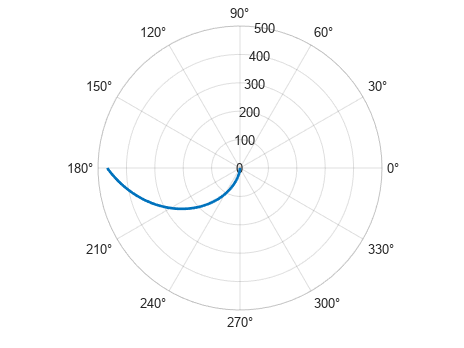

polarplot(gamma,q, "LineWidth",2)

plot(rad2deg(gamma),q, "LineWidth",2)

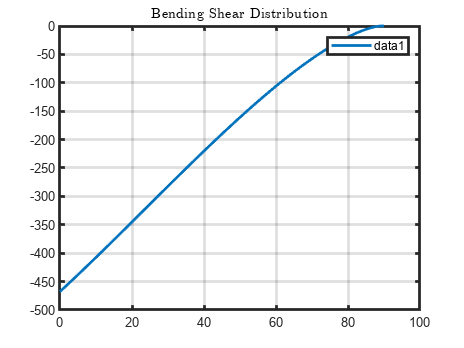


%tau(y) = P_y*Q(acos(y/r_m))/(I*t)
%fplot(@(y) tau(y),[-4,4], "LineWidth",2)

title("Bending Shear Distribution", "Interpreter","latex"); 
%xlabel("Verticle Distance, $y$, $\left(in\right)$", "Interpreter","latex", "FontSize",12); 
%xlabel("Verticle Distance, $y$, $\left(in\right)$", "Interpreter","latex", "FontSize",12); 
set(gca, "LineWidth",2); legend
% view(90,-90);
% %xlim([0,4]);
grid on;


N_x = BendingNormalLoad(r_o, t, P_y, L, x, y)

N_x = 1.0e+04 *

         0   -0.0718   -0.1436   -0.2153   -0.2871   -0.3589   -0.4307   -0.5024   -0.5742   -0.6460   -0.7178   -0.7895   -0.8613   -0.9331   -1.0049   -1.0767   -1.1484   -1.2202   -1.2920   -1.3638   -1.4355   -1.5073   -1.5791   -1.6509   -1.7226   -1.7944   -1.8662   -1.9380   -2.0098   -2.0815   -2.1533   -2.2251   -2.2969   -2.3686   -2.4404   -2.5122   -2.5840   -2.6557   -2.7275   -2.7993   -2.8711   -2.9429   -3.0146   -3.0864   -3.1582   -3.2300   -3.3017   -3.3735   -3.4453   -3.5171


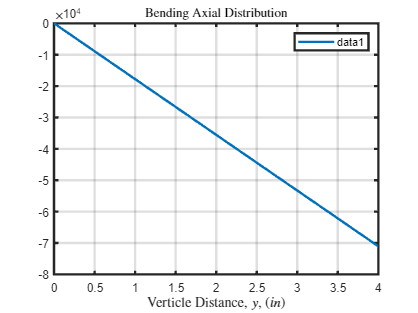

plot(y,N_x,"LineWidth",2)
title("Bending Axial Distribution", "Interpreter","latex");
xlabel("Verticle Distance, $y$, $\left(in\right)$", "Interpreter","latex", "FontSize",12); 
set(gca, "LineWidth",2); legend
grid on;

function N_xy = bendingShearFlow(r_o, t, P_y, gamma)
    r_i = r_o-t;
    I = pi * (r_o-t/2)^3 * t;
    Q = (r_o^2-r_i^2)/2.*(2*gamma - 2*sin(gamma)) .* 2/3*(r_o^3-r_i^3)./(r_o^2-r_i^2).*(sin(gamma)./gamma);
    Q = (gamma - sin(gamma)) .* 2/3*(r_o^3-r_i^3).*(sin(gamma)./gamma);
    N_xy = P_y*Q / I; % note N_xy = q shear flow
end

function N_x = axialLoad(P_x, A_cs, t)
    N_x = P_x/A_cs*t;
end

function N_xy = TorsionalShear(r_o, t, T)
    N_xy = T / (2*pi*(r_o-t/2)^2);
end

function N_x = BendingNormalLoad(r_o, t, P_y, L, x, y)
    r_m = r_o - t / 2; % average radius (in)
    I = pi * r_m^3 * t;
    N_x = P_y * (L-x) * y / I;
end